`Erfan Panahi   810198369`

## Digital Signal Processing (DSP)

# Computer Assignement 2

## ***Contents:***

***    Part 1 . Short-time Fourier Transform***

`    - Wavelet Transform`

***    Part 2 . Dual Tone Multi-Frequency (DTMF)***

***    Part 3 . Compress Images Using FFT2***

***    Part 4 . Electroencephalography (EEG)***

***    Part 5 . Introduction to Cepstrum***

# `Part 1:`***Short-time Fourier Transform***

`a. Time domain:`

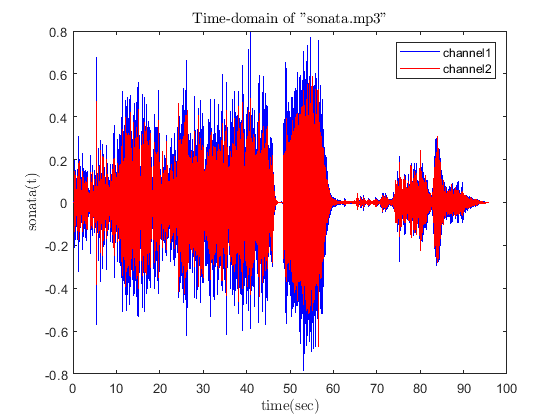

clear;
[sonata,fs] = audioread('Data\sonata.mp3');
ch1 = transpose(sonata(:,1));
ch2 = transpose(sonata(:,2));
t = 0:1/fs:(length(sonata)-1)/fs;
plot(t,ch1,'b',t,ch2,'r');
legend('channel1','channel2');
title('Time-domain of "sonata.mp3"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('sonata(t)','Interpreter','latex');

`b-1. Frequency domain:`

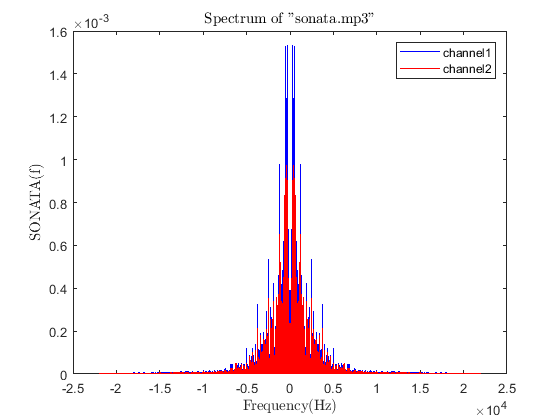

f = -fs/2:fs/length(t):(fs/2-1/length(t));
CH1_f = fftshift(fft(ch1))/length(ch1);
CH2_f = fftshift(fft(ch2))/length(ch2);
plot(f,abs(CH1_f),'b',f,abs(CH2_f),'r');
legend('channel1','channel2');
title('Spectrum of "sonata.mp3"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('SONATA(f)','Interpreter','latex');

`b-2. Power Spectrum:`

`The power spectrum is calculated as the magnitude squared of the Fourier transform (or Fourier series) of the waveform of interest:`

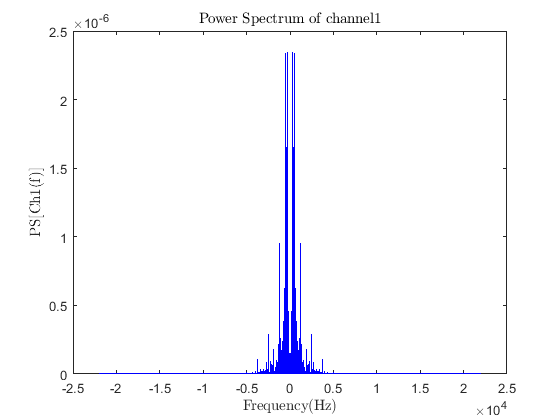

PS_CH1 = abs(CH1_f).^2;
plot(f,PS_CH1,'b');
title('Power Spectrum of channel1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('PS[Ch1(f)]','Interpreter','latex');

`c. Spectrogram:`

`Test1. `$\mathrm{window}-\mathrm{size}=100\;\;,\;\mathrm{noverlap}=10\;\;,\;\mathrm{nfft}=1000$

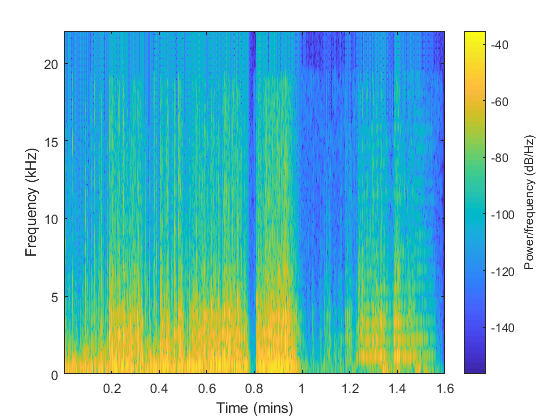

spectrogram(ch1,100,10,1000,fs,'yaxis');

`Test2. `$\textrm{window}-\textrm{size}=1000\;\;,\;\textrm{noverlap}=10\;\;,\;\textrm{nfft}=10000$

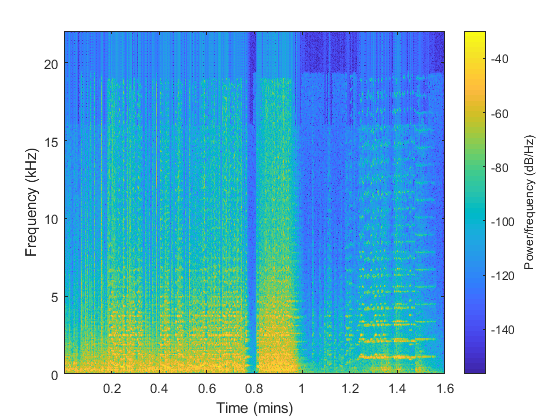

spectrogram(ch1,1000,10,10000,fs,'yaxis');

`Test3. `$\textrm{window}-\textrm{size}=10000\;,\;\textrm{noverlap}=10\;\;,\;\textrm{nfft}=10000$

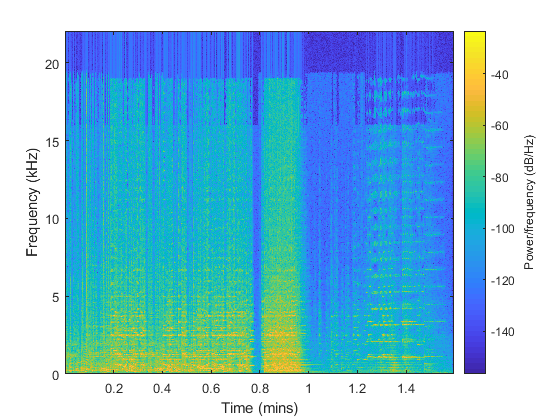

spectrogram(ch1,10000,10,10000,fs,'yaxis');

`Test4. `$\textrm{window}-\textrm{size}=100000\;\;,\;\textrm{noverlap}=10\;\;,\;\textrm{nfft}=10000$

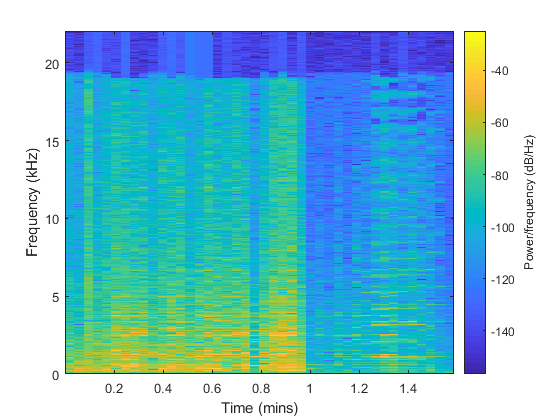

spectrogram(ch1,100000,10,10000,fs,'yaxis');

`Test5. `$\textrm{window}-\textrm{size}=1000000\;\;,\;\textrm{noverlap}=100\;\;,\;\textrm{nfft}=1000$

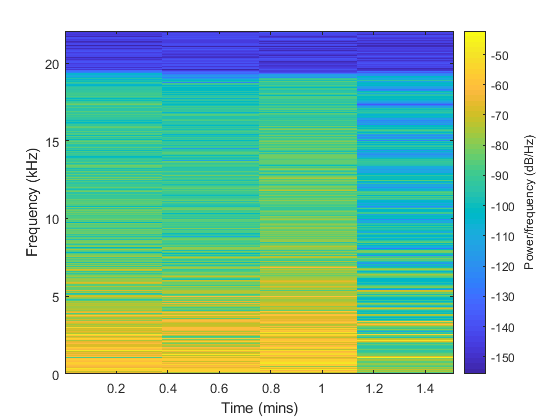

spectrogram(ch1,1000000,100,1000,fs,'yaxis');

# `Part 2:`***Dual Tone Multi-Frequency (DTMF)***

clear;
[one,fs1] = audioread('Data\dtmf\1.wav');
[two,fs2] = audioread('Data\dtmf\2.wav');
[three,fs3] = audioread('Data\dtmf\3.wav');
[four,fs4] = audioread('Data\dtmf\4.wav');
[five,fs5] = audioread('Data\dtmf\5.wav');
[six,fs6] = audioread('Data\dtmf\6.wav');
[seven,fs7] = audioread('Data\dtmf\7.wav');
[eight,fs8] = audioread('Data\dtmf\8.wav');
[nine,fs9] = audioread('Data\dtmf\9.wav');
[zero,fs0] = audioread('Data\dtmf\0.wav');
[A,fsA] = audioread('Data\dtmf\A.wav');
[B,fsB] = audioread('Data\dtmf\B.wav');
[C,fsC] = audioread('Data\dtmf\C.wav');
[D,fsD] = audioread('Data\dtmf\D.wav');
[star,fs_star] = audioread('Data\dtmf\star.wav');
[hash,fs_hash] = audioread('Data\dtmf\hash.wav');
dtmf(one,fs1,1)

ans = '1'

dtmf(two,fs2,1)

ans = '2'

dtmf(three,fs3,1)

ans = '3'

dtmf(four,fs4,1)

ans = '4'

dtmf(five,fs5,1)

ans = '5'

dtmf(six,fs6,1)

ans = '6'

dtmf(seven,fs7,1)

ans = '7'

dtmf(eight,fs8,1)

ans = '8'

dtmf(nine,fs9,1)

ans = '9'

dtmf(zero,fs0,1)

ans = '0'

dtmf(A,fsA,1)

ans = 'A'

dtmf(B,fsB,1)

ans = 'B'

dtmf(C,fsC,1)

ans = 'C'

dtmf(D,fsD,1)

ans = 'D'

dtmf(star,fs_star,1)

ans = '*'

dtmf(hash,fs_hash,1)

ans = '#'

[y,fs] = audioread('Data\dtmf\phone_number.wav');
phone_number = dtmf(y,fs,8)

phone_number = '82084180'

# `Part 3:`

`Rectangle:`

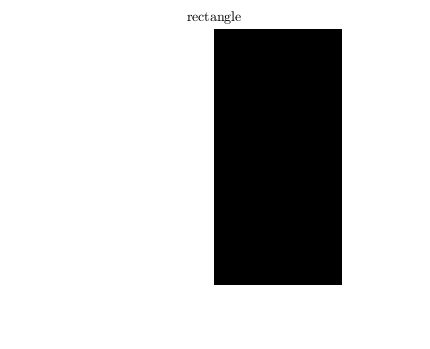

clear;
rect = [ones(256,128) zeros(256,128)];
imwrite(rect,'rectangle.jpg');
imshow(rect);
title('rectangle','Interpreter','latex');

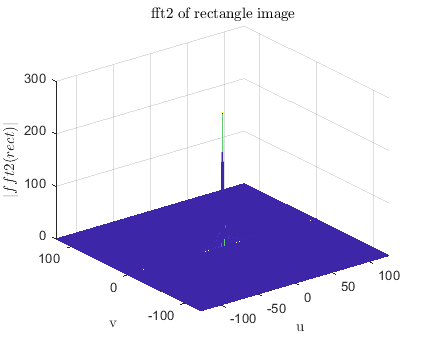

u = -128:127;
v = -128:127;
RECT = fftshift(fft2(rect));
RECT = 256*RECT/max(max(abs(RECT)));
mesh(u,v,abs(RECT));
title('fft2 of rectangle image','Interpreter','latex');
xlabel('u','Interpreter','latex'); ylabel('v','Interpreter','latex');
zlabel('$|fft2(rect)|$','Interpreter','latex');

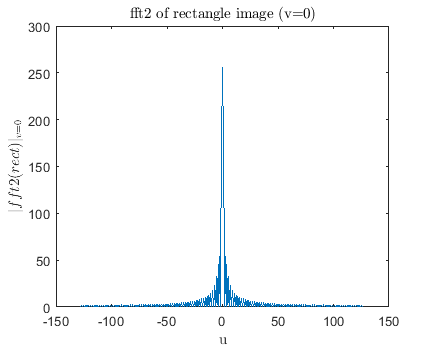

plot(u,abs(RECT(129,:)));
title('fft2 of rectangle image (v=0)','Interpreter','latex');
xlabel('u','Interpreter','latex');
ylabel('$|fft2(rect)|_{v=0} $','Interpreter','latex');

`Square:`

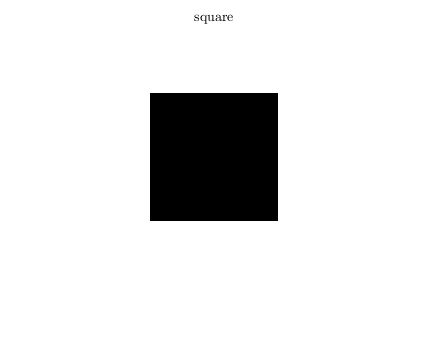

sqr = ones(256,256);
sqr(65:192,65:192) = zeros(128,128); 
imwrite(sqr,'Square.jpg');
imshow(sqr);
title('square','Interpreter','latex');

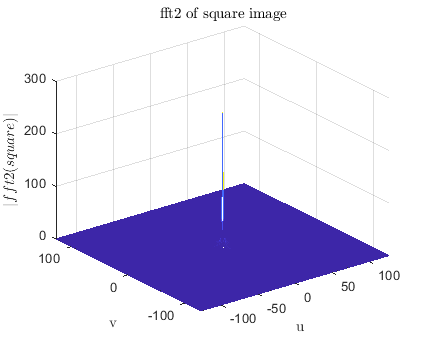

SQR = fftshift(fft2(sqr));
SQR = 256*SQR/max(max(abs(SQR)));
mesh(u,v,abs(SQR));
title('fft2 of square image','Interpreter','latex');
xlabel('u','Interpreter','latex'); ylabel('v','Interpreter','latex');
zlabel('$|fft2(square)|$','Interpreter','latex');

`Diamond:`

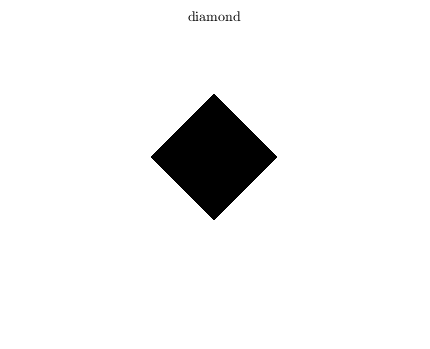

dmnd = ones(256,256);
x = round((128:-1:1)/(128+1));
y = toeplitz(x);
dmnd(65:192,65:192) = ~(y & rot90(y));
imwrite(dmnd,'Diamond.jpg');
imshow(dmnd);
title('diamond','Interpreter','latex');

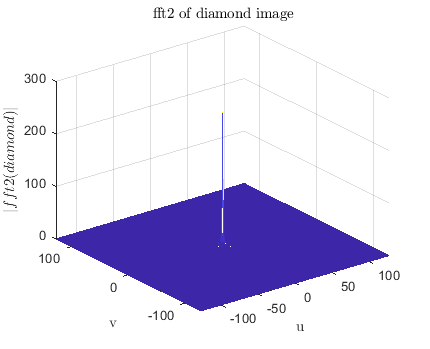

DMND = fftshift(fft2(dmnd));
DMND = 256*DMND/max(max(abs(DMND)));
mesh(u,v,abs(DMND));
title('fft2 of diamond image','Interpreter','latex');
xlabel('u','Interpreter','latex'); ylabel('v','Interpreter','latex');
zlabel('$|fft2(diamond)|$','Interpreter','latex');

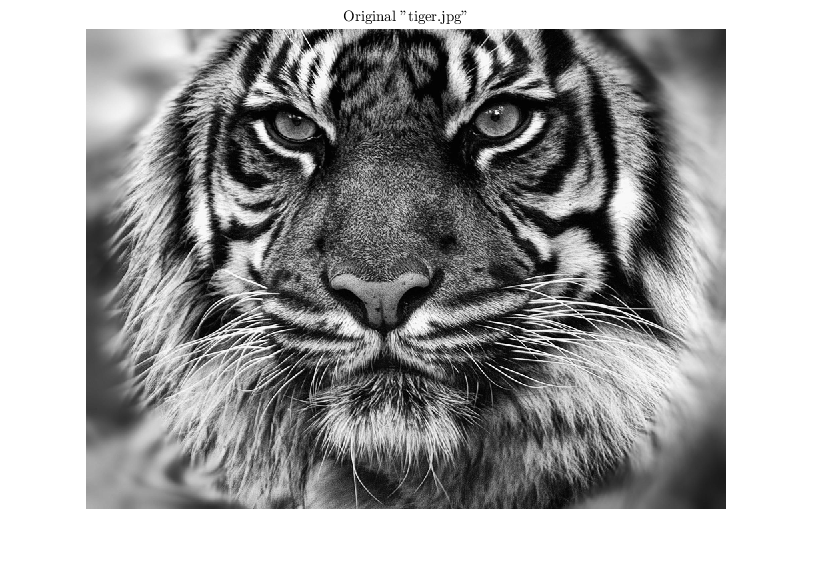

warning('off','all');
tiger = imread('Data\tiger.jpg');
imshow(tiger);
title('Original "tiger.jpg"','Interpreter','latex');

`Part a: 5%`

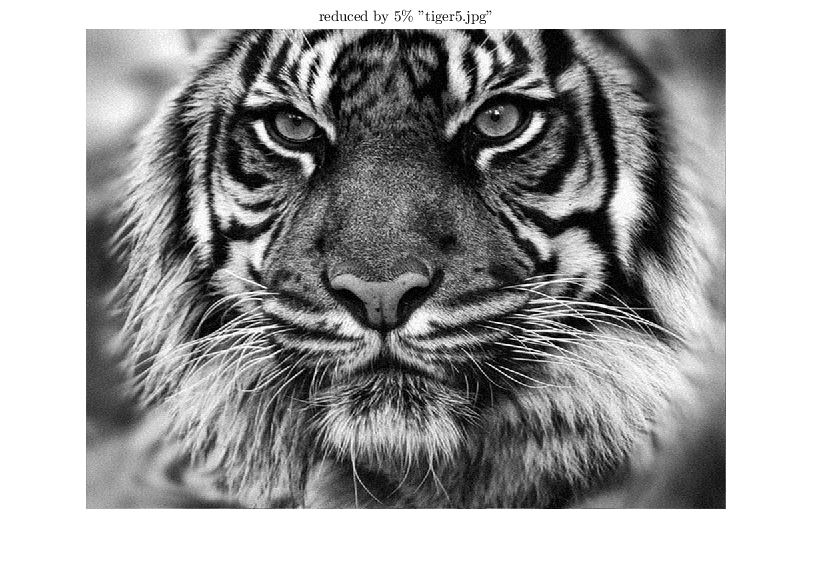

Tiger_f = fft2(tiger);
thresh_5per = 3.3e-4*max(max(abs(Tiger_f)));
dlt1 = abs(Tiger_f)<thresh_5per;
cmp5_Tiger_f = Tiger_f - dlt1.*Tiger_f;
cmp5_tiger = uint8(ifft2(cmp5_Tiger_f));
imwrite(cmp5_tiger,'tiger5.jpg');
imshow(cmp5_tiger);
title('reduced by 5$\%$ "tiger5.jpg"','Interpreter','latex');

`Part a: 5%`

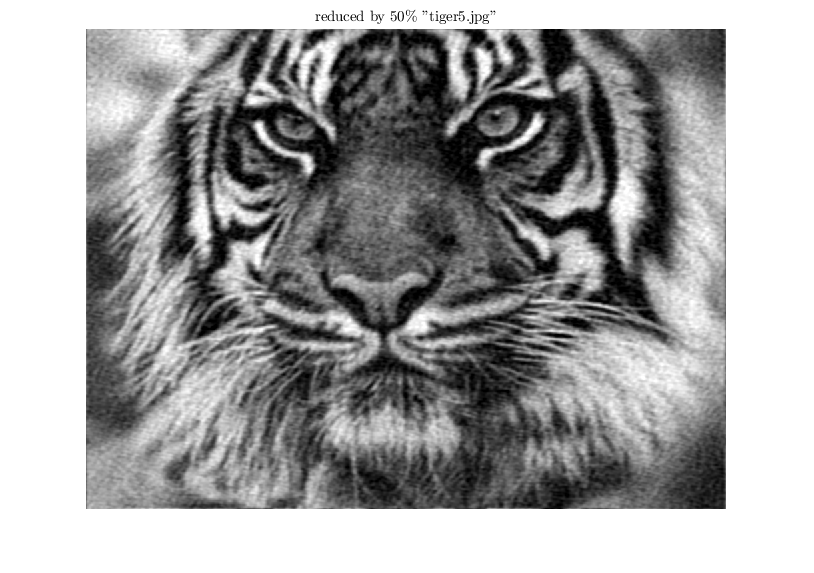

thresh_50per = 1.26e-3*max(max(abs(Tiger_f)));
dlt2 = abs(Tiger_f)<thresh_50per;
cmp50_Tiger_f = Tiger_f - dlt2.*Tiger_f;
cmp50_tiger = uint8(ifft2(cmp50_Tiger_f));
imwrite(cmp50_tiger,'tiger50.jpg');
imshow(cmp50_tiger);
title('reduced by 50$\%$ "tiger5.jpg"','Interpreter','latex');

# `Part 4:`

`  Load:`

clear;
v1 = load('Data\v1.mat','-mat');
v2 = load('Data\v2.mat','-mat');
v4 = load('Data\v4.mat','-mat');
v1_t = v1.val(1,:);
v2_t = v2.val(1,:);
v3_t = v2.val(1,:);
fs = length(v1_t)/10;
t = 0:1/fs:10-1/fs;
f = -fs/2:fs/length(t):(fs/2-1/length(t));
V1_f = fftshift(fft(v1_t))/length(v1_t);
V2_f = fftshift(fft(v2_t))/length(v2_t);
V3_f = fftshift(fft(v3_t))/length(v3_t);

`removing noise:`

L = length(f);
f0 = L/2+1;
f1 = L/fs;
V1_f(f0-0.5*f1:f0+0.5*f1) = 0;
V2_f(f0-0.5*f1:f0+0.5*f1) = 0;
V3_f(f0-0.5*f1:f0+0.5*f1) = 0;

`  Part a:`

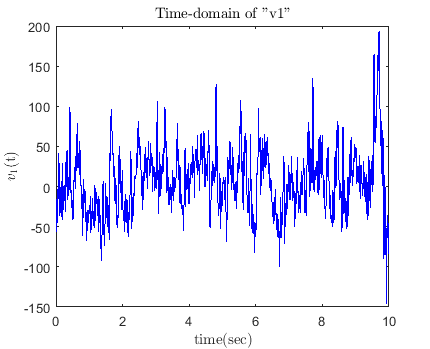

plot(t,v1_t,'b');
title('Time-domain of "v1"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$v_1$(t)','Interpreter','latex');

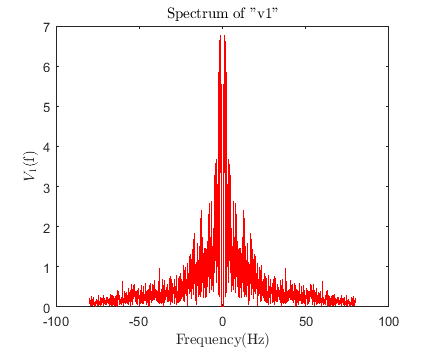

plot(f,abs(V1_f),'r');
title('Spectrum of "v1"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$V_1$(f)','Interpreter','latex');

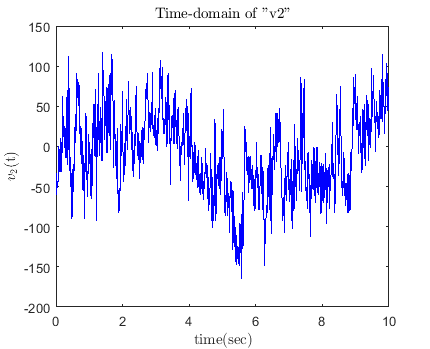


plot(t,v2_t,'b');
title('Time-domain of "v2"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$v_2$(t)','Interpreter','latex');

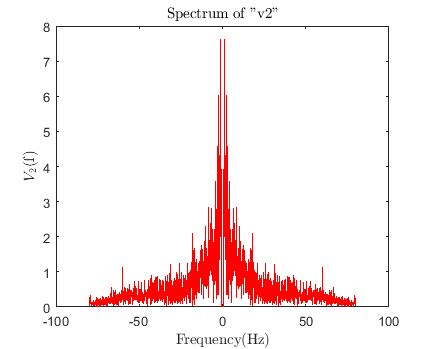

plot(f,abs(V2_f),'r');
title('Spectrum of "v2"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$V_2$(f)','Interpreter','latex');

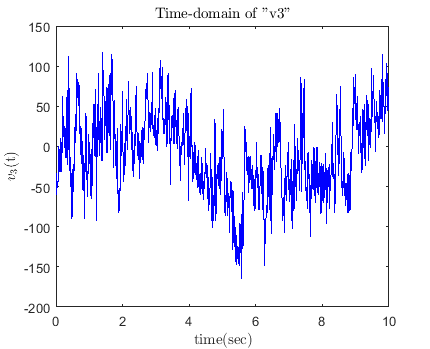


plot(t,v3_t,'b');
title('Time-domain of "v3"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$v_3$(t)','Interpreter','latex');

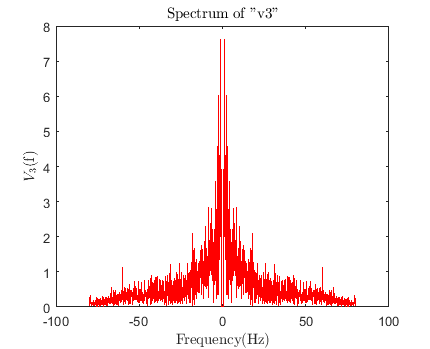

plot(f,abs(V3_f),'r');
title('Spectrum of "v3"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$V_3$(f)','Interpreter','latex');

`Part b:`

- `Delta (0.5-4 Hz):`

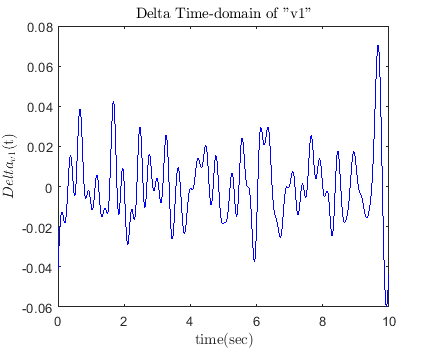

Delta_V1 = zeros(1,length(f));
Delta_V1(f0+0.5*f1:f0+4*f1) = V1_f(f0+0.5*f1:f0+4*f1);
Delta_V1(f0-4*f1:f0-0.5*f1) = V1_f(f0-4*f1:f0-0.5*f1);
delta_v1_t = ifft(ifftshift(Delta_V1));
plot(t,delta_v1_t,'b');
title('Delta Time-domain of "v1"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$Delta_{v1}$(t)','Interpreter','latex');

- `Theta (4-8 Hz):`

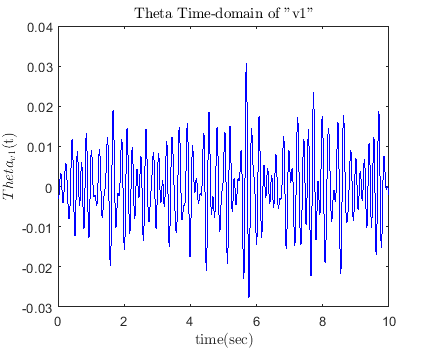

Theta_V1 = zeros(1,length(f));
Theta_V1(f0+4*f1:f0+8*f1) = V1_f(f0+4*f1:f0+8*f1);
Theta_V1(f0-8*f1:f0-4*f1) = V1_f(f0-8*f1:f0-4*f1);
Theta_v1_t = ifft(ifftshift(Theta_V1));
plot(t,Theta_v1_t,'b');
title('Theta Time-domain of "v1"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$Theta_{v1}$(t)','Interpreter','latex');

- `Alpha (8-13 Hz):`

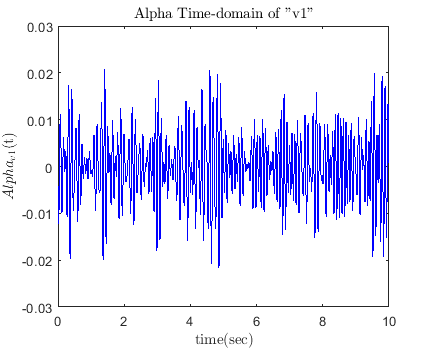

Alpha_V1 = zeros(1,length(f));
Alpha_V1(f0+8*f1:f0+13*f1) = V1_f(f0+8*f1:f0+13*f1);
Alpha_V1(f0-13*f1:f0-8*f1) = V1_f(f0-13*f1:f0-8*f1);
Alpha_v1_t = ifft(ifftshift(Alpha_V1));
plot(t,Alpha_v1_t,'b');
title('Alpha Time-domain of "v1"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$Alpha_{v1}$(t)','Interpreter','latex');

- `Beta (13-35 Hz):`

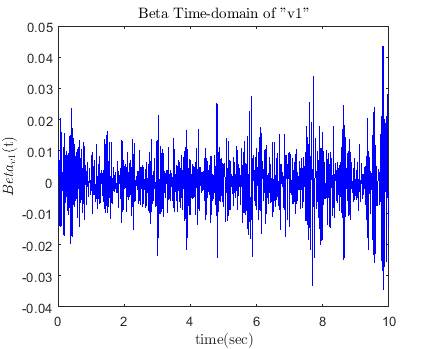

Beta_V1 = zeros(1,length(f));
Beta_V1(f0+13*f1:f0+35*f1) = V1_f(f0+13*f1:f0+35*f1);
Beta_V1(f0-35*f1:f0-13*f1) = V1_f(f0-35*f1:f0-13*f1);
Beta_v1_t = ifft(ifftshift(Beta_V1));
plot(t,Beta_v1_t,'b');
title('Beta Time-domain of "v1"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$Beta_{v1}$(t)','Interpreter','latex');

- `Gamma (35+ Hz):`

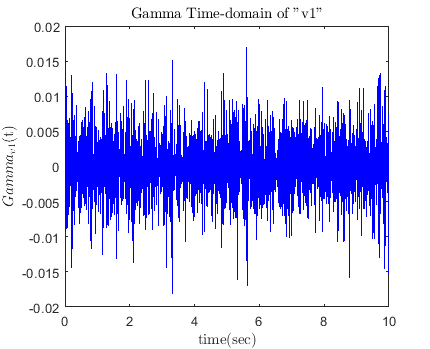

Gamma_V1 = zeros(1,length(f));
Gamma_V1(f0+35*f1:length(f)) = V1_f(f0+35*f1:length(f));
Gamma_V1(1:f0-35*f1) = V1_f(1:f0-35*f1);
Gamma_v1_t = ifft(ifftshift(Gamma_V1));
plot(t,Gamma_v1_t,'b');
title('Gamma Time-domain of "v1"','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$Gamma_{v1}$(t)','Interpreter','latex');

# `Part 5:`

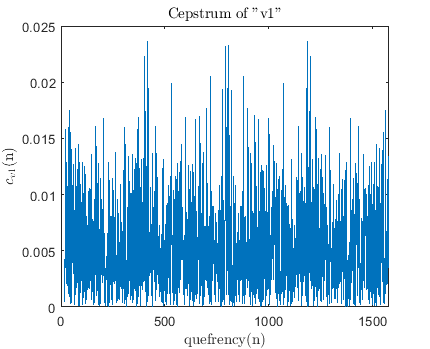

c_v1 = cepstrum(v1_t);
plot(19:length(c_v1)-21,abs(c_v1(20:length(c_v1)-20)));
title('Cepstrum of "v1"','Interpreter','latex');
xlabel('quefrency(n)','Interpreter','latex');
ylabel('$c_{v1}$(n)','Interpreter','latex');

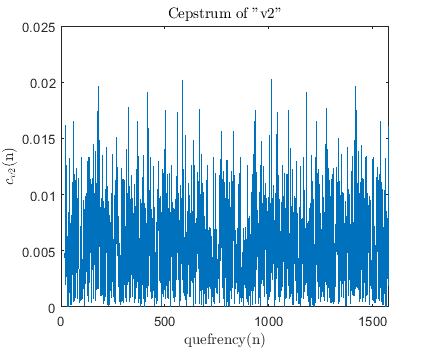

c_v2 = cepstrum(v2_t);
plot(19:length(c_v2)-21,abs(c_v2(20:length(c_v2)-20)));
title('Cepstrum of "v2"','Interpreter','latex');
xlabel('quefrency(n)','Interpreter','latex');
ylabel('$c_{v2}$(n)','Interpreter','latex');

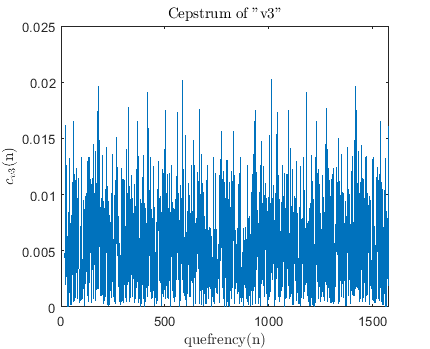

c_v3 = cepstrum(v3_t);
plot(19:length(c_v3)-21,abs(c_v3(20:length(c_v3)-20)));
title('Cepstrum of "v3"','Interpreter','latex');
xlabel('quefrency(n)','Interpreter','latex');
ylabel('$c_{v3}$(n)','Interpreter','latex');

`Sampling rate:`

fs = length(v1_t)/10

fs = 160

`peak of frequency domain: `

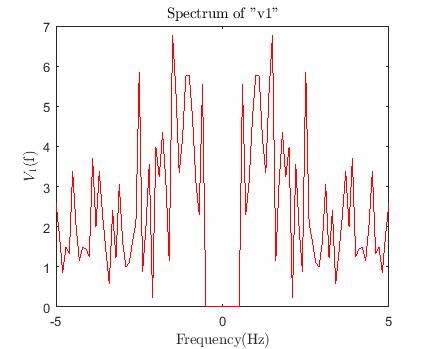

plot(f,abs(V1_f),'r');
xlim([-5 5]);
title('Spectrum of "v1"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$V_1$(f)','Interpreter','latex');

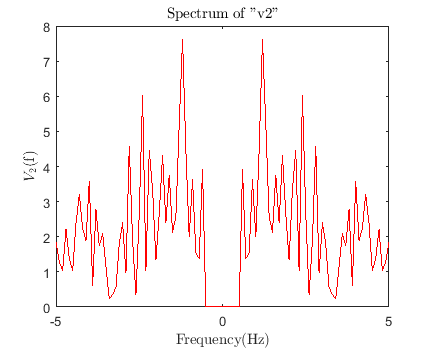

plot(f,abs(V2_f),'r');
xlim([-5 5]);
title('Spectrum of "v2"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$V_2$(f)','Interpreter','latex');

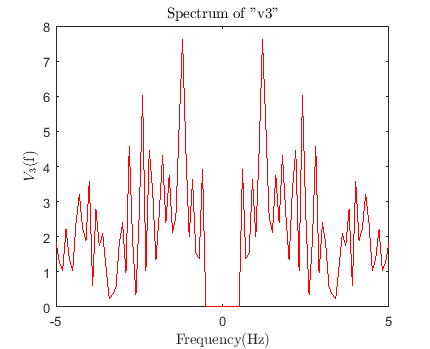

plot(f,abs(V3_f),'r');
xlim([-5 5]);
title('Spectrum of "v3"','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$V_3$(f)','Interpreter','latex');

# `Functions:`

`DTFT:`

function keyboard = dtmf(y,fs,n)
    keypad = ['1' '2' '3' 'A';
              '4' '5' '6' 'B';
              '7' '8' '9' 'C';
              '*' '0' '#' 'D'];
    fr = [697 770 852 941];
    fc = [1209 1336 1477 1633];
    L = length(y)/n;
    f = -fs/2:fs/L:(fs/2-1/L);
    keyboard = [];
    for k = 0:n-1
        new = y(k*L+1:(k+1)*L);
        NEWF = abs(fftshift(fft(new)));
        rNEWF = NEWF(L/2:L/2+1000*L/fs);
        cNEWF = NEWF(L/2+1000*L/fs:L/2+2000*L/fs);
        row = find(NEWF == max(rNEWF),1,'last');
        col = find(NEWF == max(cNEWF),1,'last');
        Nrow = abs(fr-f(row));
        Ncol = abs(fc-f(col));
        i = find(Nrow == min(Nrow),1);
        j = find(Ncol == min(Ncol),1);
        keyboard = [keyboard keypad(i,j)];
    end
end

`Cepstrum:`

function c = cepstrum (x)
    X = fft(x);
    C = log10(abs(X));
    c = ifft(C);
end